clear all; close all; clc;
syms C_D_0 rho r g phi W2S S V_g L_g L_c A e V_T

% V_ave == 1/( () + 1/V_g ) 

V_s = (C_D_0*(1/2)*rho*V_g^2*S + L_g^2 / (pi*A*e * (1/2)*rho*V_g^2*S)) / L_g^(3/2) * sqrt(W2S*S)

$$V\_s = \frac{\sqrt{S\,\mathrm{W2S}}\,\left(\frac{C_{D,0}\,S\,{V_{g}}^{2}\,\rho }{2}+\frac{2\,{L_{g}}^{2}}{A\,S\,{V_{g}}^{2}\,e\,\rho \,\pi }\right)}{{L_{g}}^{3/2}}$$


V_c = V_T - ((1/2)*rho*r*g*tan(phi)*C_D_0*S + L_c^2 / (pi*A*e * (1/2)*rho*r*g*tan(phi)*S)) / (L_c^(3/2) * cos(phi)^(2/3)) * sqrt(r*g*tan(phi)*W2S*S)

$$V\_c = V_{T}-\frac{\left(\frac{C_{D,0}\,S\,g\,r\,\rho \,\tan\left(\varphi \right)}{2}+\frac{2\,{L_{c}}^{2}}{A\,S\,e\,g\,r\,\rho \,\pi \,\tan\left(\varphi \right)}\right)\,\sqrt{S\,\mathrm{W2S}\,g\,r\,\tan\left(\varphi \right)}}{{L_{c}}^{3/2}\,{\cos\left(\varphi \right)}^{2/3}}$$


V_ave = 1/( (V_s^(-1) / V_c) + 1/V_g )

$$V\_ave = \frac{1}{\frac{1}{V_{g}}+\frac{{L_{g}}^{3/2}}{\sqrt{S\,\mathrm{W2S}}\,\left(V_{T}-\frac{\left(\frac{C_{D,0}\,S\,g\,r\,\rho \,\tan\left(\varphi \right)}{2}+\frac{2\,{L_{c}}^{2}}{A\,S\,e\,g\,r\,\rho \,\pi \,\tan\left(\varphi \right)}\right)\,\sqrt{S\,\mathrm{W2S}\,g\,r\,\tan\left(\varphi \right)}}{{L_{c}}^{3/2}\,{\cos\left(\varphi \right)}^{2/3}}\right)\,\left(\frac{C_{D,0}\,S\,{V_{g}}^{2}\,\rho }{2}+\frac{2\,{L_{g}}^{2}}{A\,S\,{V_{g}}^{2}\,e\,\rho \,\pi }\right)}}$$



% % check the partial derivatives
% dV_ave_d_L_g = diff(V_ave,L_g);
% dV_ave_d_L_c = diff(V_ave,L_c);
% dV_ave_d_V_g = diff(V_ave,V_g);
% dV_ave_dS = diff(V_ave,S)

clear all; close all; clc;

W_MGTO = 7354.9875; % Maximum Gross Takeoff Weight (N)
W_gross = W_MGTO; % Gorss Wegiht (N)
W_oe = W_gross; % operating empty weight (N)
category = "Aerobatic"; % Max g limit catregory
S = 17.53; % Wing Area (m^2)
A = 22.82; % aspect ratio (~)
Lambda_LE = deg2rad(-2); % leading edge sweep angle (radians)
lambda = .5/2.1; % taper ratio (~)
M = 0; % Mach number (~) (for incompressible M = 0)
alpha_stall = deg2rad(15); % stall angle (radians)
alt = 0; % altitude (m)
C_D_0 = .00829; % minimum drag coeefficient (Backed out from L/D max)

% is is a GUESSED value
e = .9% oswald efficiency factor (GUESS)

e = 0.9000


% % Here is the Data for our Aircraft
W= 9690; % Maximum Gross Takeoff Weight (N)
category = "Aerobatic"; % Max g limit catregory
S = 17.53; % Wing Area (m^2)
A = 22.82; % aspect ratio (~)
[~, ~, ~, rho] = atmosisa(0); % atmospheric density (kg/m^3)
W2S = W/S;
g = 9.81; % acceleration due to gravity (m/s)

V_T = 4; % thermal Velocity (m/s)
r = 80; % radius (m)
phi = deg2rad(45); % bank angle (radains)

syms V_g L_g L_c

V_s = (C_D_0*(1/2)*rho*V_g^2*S + L_g^2 / (pi*A*e * (1/2)*rho*V_g^2*S)) / L_g^(3/2) * sqrt(W2S*S)

$$V\_s = \frac{\sqrt{9690}\,\left(\frac{5131121327557918263\,{V_{g}}^{2}}{57646075230342348800}+\frac{7036874417766400\,{L_{g}}^{2}}{4875013603210859397\,{V_{g}}^{2}}\right)}{{L_{g}}^{3/2}}$$


V_c = V_T - ((1/2)*rho*r*g*tan(phi)*C_D_0*S + L_c^2 / (pi*A*e * (1/2)*rho*r*g*tan(phi)*S)) / (L_c^(3/2) * cos(phi)^(2/3)) * sqrt(r*g*tan(phi)*W2S*S)

$$V\_c = 4-\frac{8279610396142645248\,\left(\frac{4294967296\,{L_{c}}^{2}}{2335150558959889}+\frac{4915654318685857}{70368744177664}\right)}{2383006262043839\,{L_{c}}^{3/2}}$$


V_ave = 1/( (V_s^(-1) / V_c) + 1/V_g )

$$V\_ave = \frac{1}{\frac{1}{V_{g}}-\frac{\sqrt{9690}\,{L_{g}}^{3/2}}{9690\,\left(\frac{8279610396142645248\,\left(\frac{4294967296\,{L_{c}}^{2}}{2335150558959889}+\frac{4915654318685857}{70368744177664}\right)}{2383006262043839\,{L_{c}}^{3/2}}-4\right)\,\left(\frac{5131121327557918263\,{V_{g}}^{2}}{57646075230342348800}+\frac{7036874417766400\,{L_{g}}^{2}}{4875013603210859397\,{V_{g}}^{2}}\right)}}$$


% plotting
n_plotPoints = 1000;

V_g_min_plot = 0;
V_g_max_plot = 200;

L_g_min_plot = 0;
L_g_max_plot = 2*W;

L_c = W * .95;
% L_c_min_plot = 0;
% L_c_max_plot = 2*W;


V_g = linspace(V_g_min_plot, V_g_max_plot, n_plotPoints);
L_g = linspace(L_g_min_plot, L_g_max_plot, n_plotPoints);
%L_c = linspace(L_c_min_plot, L_c_max_plot, n_plotPoints);

[V_g, L_g] = meshgrid(V_g, L_g);

V_s = (C_D_0.*(1/2).*rho.*V_g.^2.*S + L_g.^2 ./ (pi.*A.*e .* (1/2).*rho.*V_g.^2.*S)) ./ L_g.^(3/2) .* sqrt(W2S.*S)

V_s = 1.0e+03 *

       NaN       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf       Inf
       Inf    0.0156    0.0039    0.0018    0.0010    0.0007    0.0006    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0014    0.0015    0.0017    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0035    0.0037    0.0040    0.0042    0.0045    0.0048    0.0050    0.0053    0.0056    0.0059    0.0063    0.0066    0.0069    0.0073    0.0076    0.0080    0.0083    0.0087    0.0091  


V_c = V_T - ((1/2).*rho.*r.*g.*tan(phi).*C_D_0*S + L_c^2 ./ (pi.*A.*e .* (1/2).*rho.*r.*g.*tan(phi).*S)) ./ (L_c.^(3/2) .* cos(phi).^(2/3)) .* sqrt(r.*g.*tan(phi).*W2S.*S)

V_c = 3.1121


V_ave = 1./( (V_s.^(-1) ./ V_c) + 1./V_g )

V_ave =        NaN    0.2002    0.4004    0.6006    0.8008    1.0010    1.2012    1.4014    1.6016    1.8018    2.0020    2.2022    2.4024    2.6026    2.8028    3.0030    3.2032    3.4034    3.6036    3.8038    4.0040    4.2042    4.4044    4.6046    4.8048    5.0050    5.2052    5.4054    5.6056    5.8058    6.0060    6.2062    6.4064    6.6066    6.8068    7.0070    7.2072    7.4074    7.6076    7.8078    8.0080    8.2082    8.4084    8.6086    8.8088    9.0090    9.2092    9.4094    9.6096    9.8098
         0    0.1994    0.3877    0.5416    0.6422    0.6941    0.7221    0.7511    0.7948    0.8574    0.9380    1.0340    1.1427    1.2618    1.3893    1.5239    1.6643    1.8097    1.9594    2.1127    2.2693    2.4287    2.5907    2.7549    2.9213    3.0894    3.2593    3.4307    3.6036    3.7778    3.9532    4.1297    4.3073    4.4858    4.6653    4.8456    5.0267    5.2085    5.3911    5.5743    5.7582    5.9426    6.1277    6.3132    6.4992    6.6857    6.8727    7.0601    7.2479 

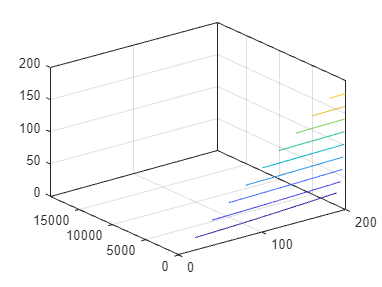


contour3(V_g, L_g, V_ave)

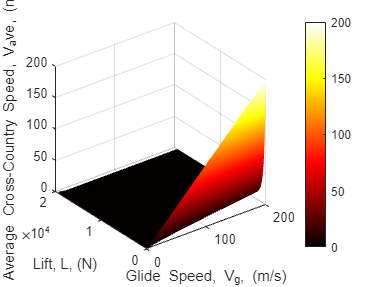


surf(V_g, L_g, V_ave, "EdgeColor","none"); colorbar; colormap("hot");
xlabel("Glide Speed, V_g, (m/s)"); ylabel("Lift, L, (N)"); zlabel("Average Cross-Country Speed, V_ave, (m/s)");